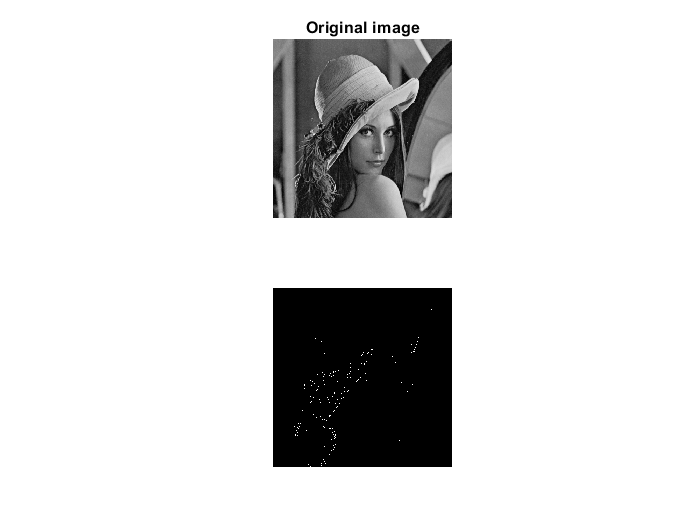

clear all;
close all;
clc;

img = imread('lena.jpg');
subplot(2,1,1);
imshow(img);
title('Original image');
hold on;
[size_rows, size_columns] = size(img);
img_double = double(img);
threshold = 100;
% zero_padding the boundary.
img_after_zero_padding = zeros(size_rows+2, size_columns+2);
for index_x = 1:size_columns
    for index_y = 1:size_rows
        img_after_zero_padding(index_x+1,index_y+1) = img_double(index_x, index_y);
    end
end
% Start calculating
img_edge_final = zeros(size_rows, size_columns);
for i = 1:size_rows
    for j = 1:size_columns
        if((4*img_after_zero_padding(i+1, j+1)-img_after_zero_padding(i+1, j)-...
                img_after_zero_padding(i+1, j+2)-img_after_zero_padding(i, j+1)-...
                img_after_zero_padding(i+2, j+1))>threshold)
            img_edge_final(i, j) = 1;
        else
            img_edge_final(i, j) = 0;
        end
    end
end
subplot(2, 1, 2);
imshow(img_edge_final);